SAMPLE CODE

- Don't forget to add the relevant codes to your MATLAB path

- If code fails to fit, just draw a new initial guess before re-running nlinfit

% clear variables from workspace and close figures

clear
close all

% load in image series 
% for example, load sample simulation provided under demo/

uiopen('*.mat')

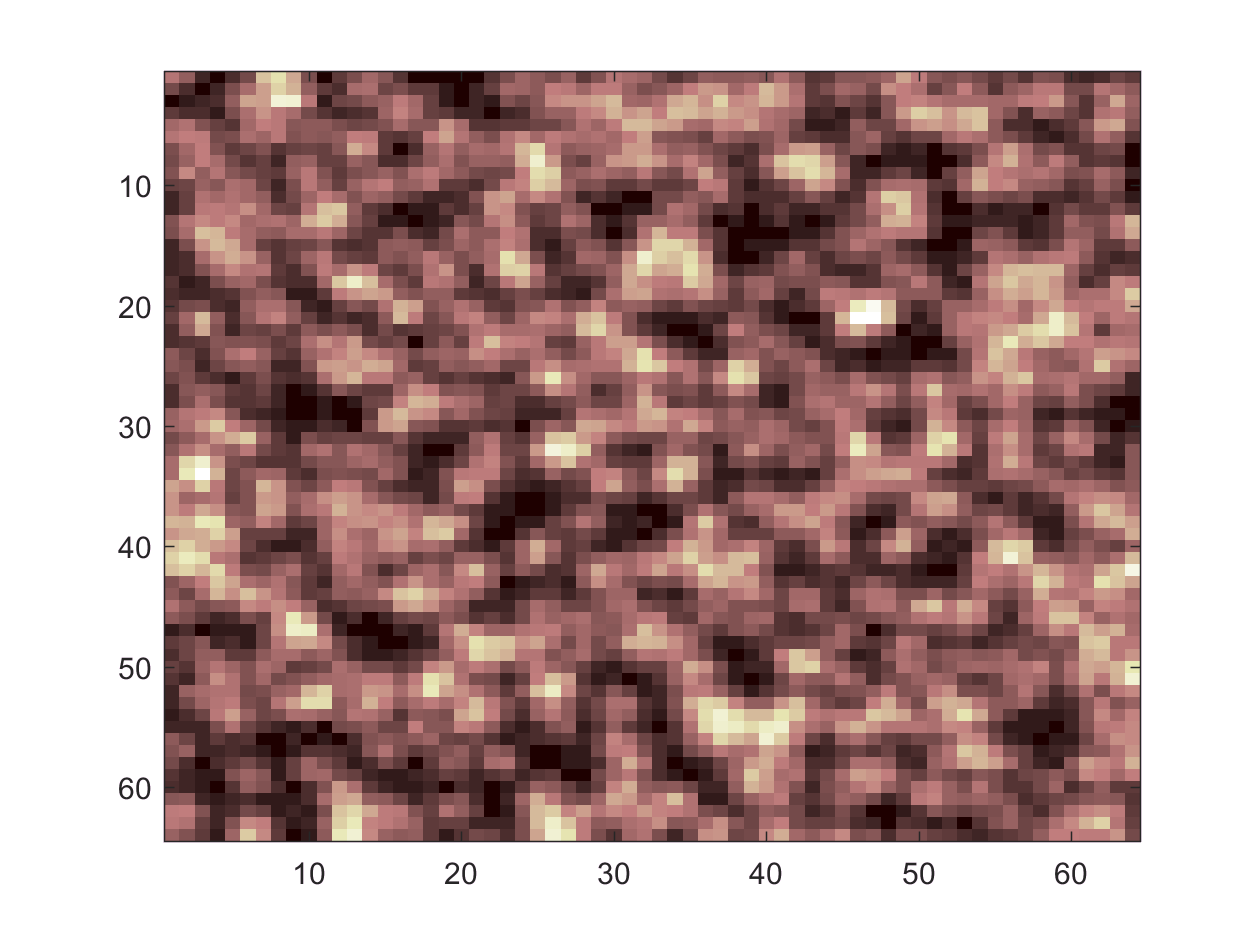

% view first image in image series

imagesc(J(:,:,1))
colormap(pink)

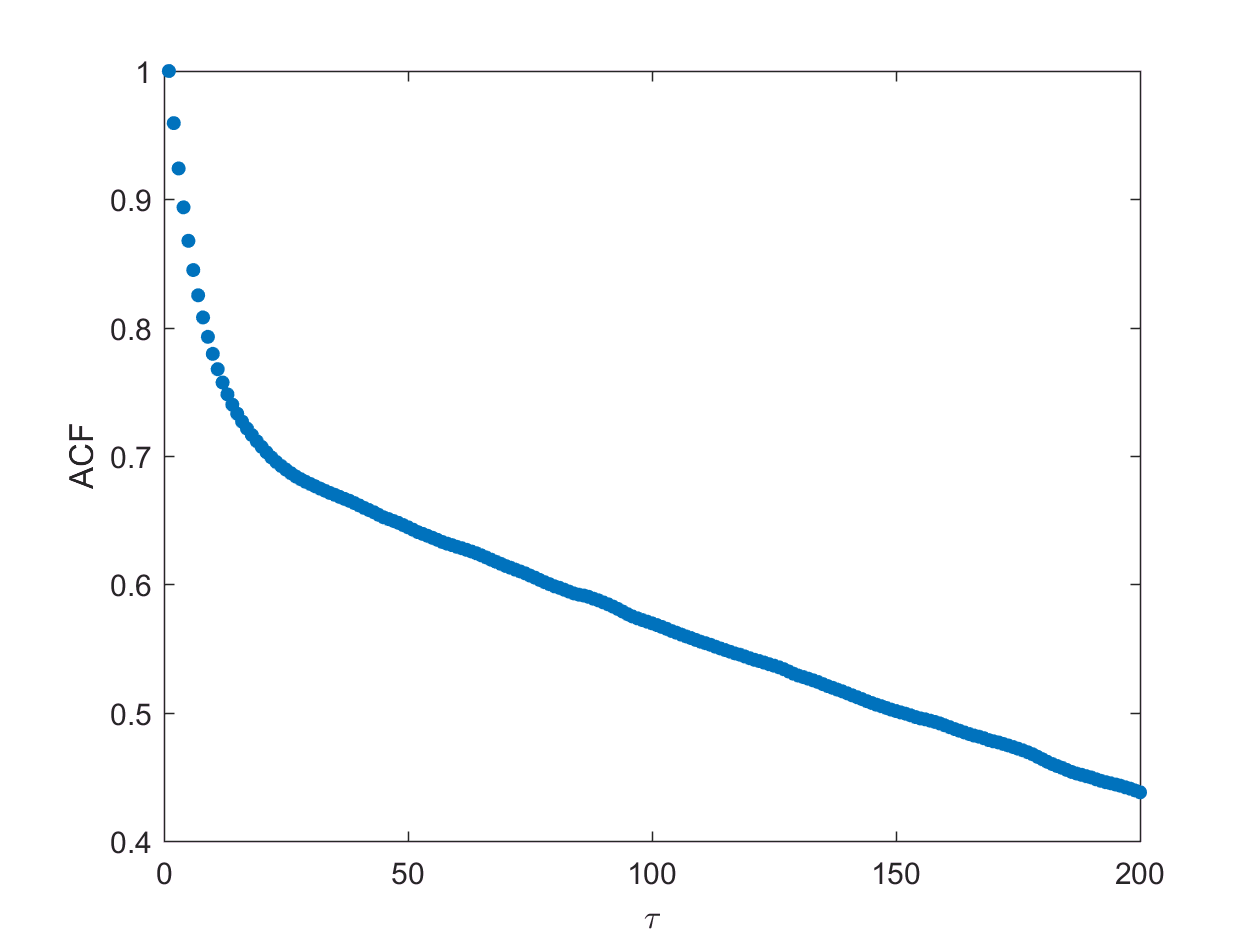

% compute average temporal autocorrelation with windowed spatial mean subtraction (10x10 window)

phi_tau = TICS(J,'window',10);

% range of time-lags to plot/fit

tau_vec = 1:200;

% compute ACF (normalize by autocorrelation at tau = 1)

acf = phi_tau./phi_tau(2);

% plot ACF over lag range tau_vec

plot(tau_vec,acf(tau_vec+1),'.','markersize',16);
ax = gca;
xlabel('\tau')
ylabel('ACF')

% if fit fails, re-run this section

% initialize fitting function (in this case, the simulation assumes bleaching only from the off-state so this is the appropriate model)
% the parameters fit are rates (kon,koff,kp), in that order

fit_fun = @(p,tau) offBleachACF(p(1:3),tau,length(acf));

% initial guess for (kon,koff,kp)

x0 = [rand(1,2),1e-4];

% options for nlinfit (non-linear fitting function in MATLAB)

opts = statset('nlinfit');
opts.Display = 'final';
opts.MaxIter=5000;

% non-linear fit to ACF

[x,R,~,CovB,MSE,~] = nlinfit(tau_vec,acf(tau_vec+1)',fit_fun,x0,opts);

Iterations terminated: relative change in SSE less than OPTIONS.TolFun


% confidence intervals on fitted paramters (95%)

ci = nlparci(x,R,'covar',CovB);

% display fitted parameters (the simulated parameters were [k_on,k_off,k_p]=[0.1,0.05,1e-2])

disp(x)

   0.102715922488208   0.050128168319537   0.009614322495163



% display errors on fit

disp(ci)

   0.101188738344447   0.104243106631969
   0.049461646836790   0.050794689802283
   0.009560320697719   0.009668324292607



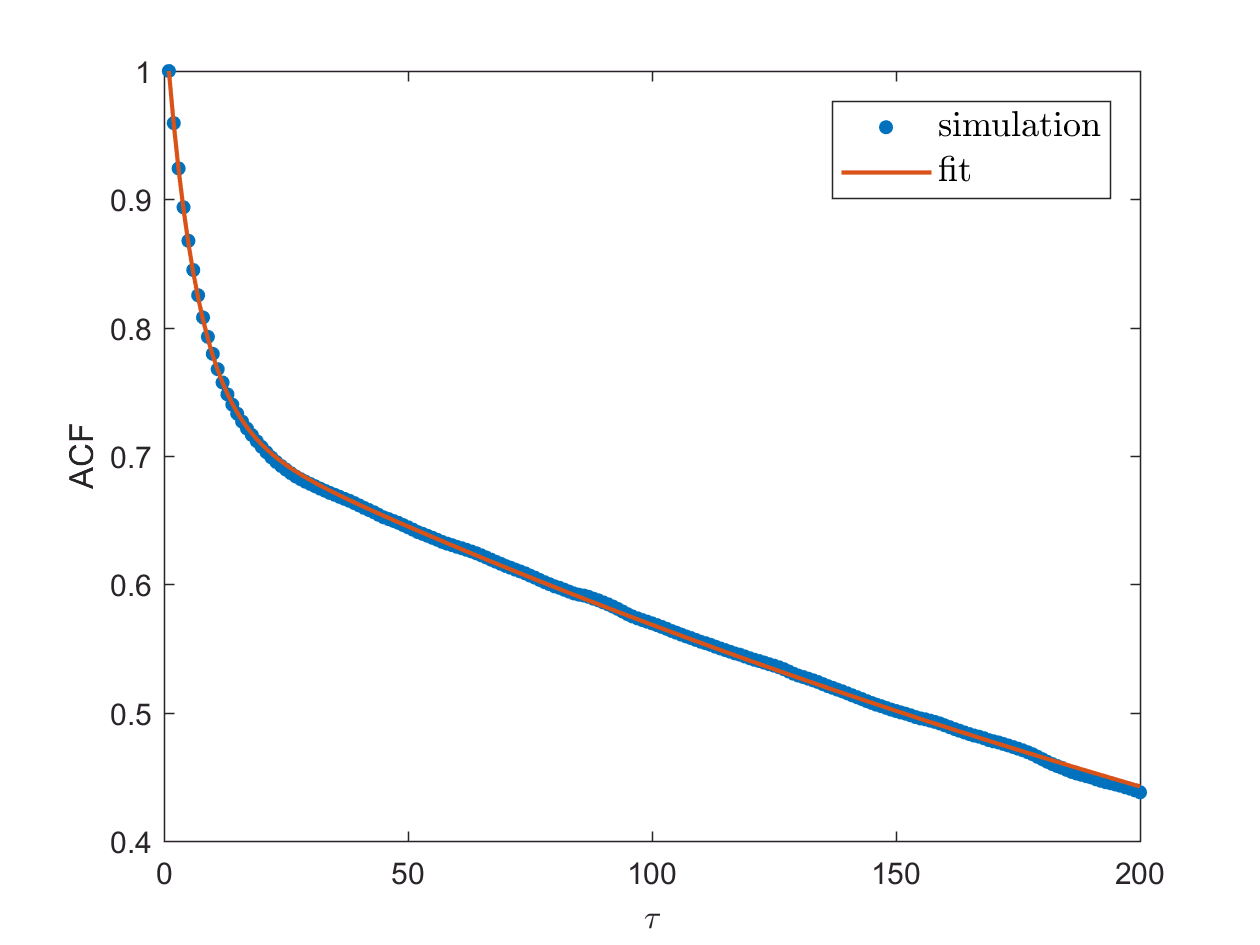

% overlay fit on plotted ACF

h = figure;

copyobj(ax,h)
ax_new = gca;
hold on

plot(ax_new,tau_vec,fit_fun(x,tau_vec),'linewidth',1.4);
legend({'simulation','fit'},'Interpreter','latex','FontSize',12)

hold off